# **Gemelo Digital - Bicineta**

## **Minimos Cuadrados Recursivo - Modelo ARX (AutoRegressive with eXogenous inputs)**

**Entradas**

- **Acelerador -->    x1**

- **Voltaje        -->    x2**

- **Altitud        -->    x3**

**Salidas**

- **Velocidad    -->    y1**

- **Corriente     -->    y2**

% Tiempo de muestreo T = 1.4853s
% Datos para Simulink
t = linspace(0, 4860, 3273)';
x1 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Aceleracion_V_Acc_"))];
x2 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Voltaje_V_"))];
x3 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Altitud"))];

y1 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Velocidad_RPM_"))];
y2 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Corriente_A_"))];

% Codigo Matlab - Cargando datos para hallar theta

X1 = table2array(TakeDataBicinetaPath_1_2_3(:,"Aceleracion_V_Acc_"));
X2 = table2array(TakeDataBicinetaPath_1_2_3(:,"Voltaje_V_"));
X3 = table2array(TakeDataBicinetaPath_1_2_3(:,"Altitud"));

Y1 = table2array(TakeDataBicinetaPath_1_2_3(:,"Velocidad_RPM_"));
Y2 = table2array(TakeDataBicinetaPath_1_2_3(:,"Corriente_A_"));

Y = [Y1 Y2];
U = [X1 X2 X3];

theta = zeros(15,2);
P = eye(15);
Y_est = zeros(3273, 2);

for k = 4:3273
    H = [-Y(k-1,:) -Y(k-2,:) -Y(k-3,:) U(k-1,:) U(k-2,:) U(k-3,:)]';
    Ym = Y(k,:); % Y medido
    Ye = H'*theta; % Y estimado
    theta = theta + P*H/(1+H'*P*H)*(Ym-Ye);
    P = P-P*H*H'*P/(1+H'*P*H);
    Y_est(k-3,:) = Ye;
end

## Error de estimación

format bank
E = sqrt((1/3273)*sum((Y_est-Y).^2));
disp(E)

         87.93          4.38



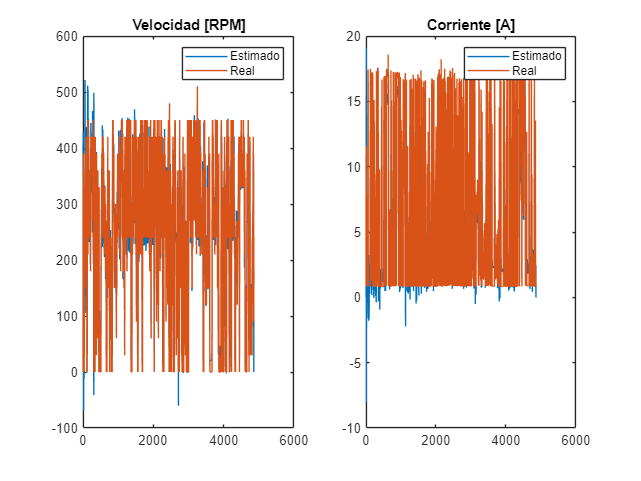

figure;
subplot(1, 2, 1)
plot(t,Y_est(:,1), t, Y(:,1))
legend('Estimado', 'Real')
title('Velocidad [RPM]')
subplot(1, 2, 2)
plot(t, Y_est(:,2), t, Y(:,2))
legend('Estimado', 'Real')
title('Corriente [A]')

## Parametros Resultantes [Velocidada, Corriente]

theta

theta =          -0.94          0.00
         -2.20         -0.53
          0.03          0.00
          0.53         -0.23
          0.06         -0.00
          0.99         -0.06
          9.17          0.64
         -3.69         -0.07
         -0.15          0.05
         11.53         -1.98


# **Evaluación del Modelo**

% Cargando datos de evaluación

% Entradas
X1eval = table2array(TakeDataBicinetaPath4(:, 'Aceleracion_V_Acc_'));
X2eval = table2array(TakeDataBicinetaPath4(:, 'Voltaje_V_'));
X3eval = table2array(TakeDataBicinetaPath4(:, 'Altitud'));
Ueval = [X1eval X2eval X3eval];

% Salidas
Y1eval = table2array(TakeDataBicinetaPath4(:, 'Velocidad_RPM_'));
Y2eval = table2array(TakeDataBicinetaPath4(:, 'Corriente_A_'));
Yeval = [Y1eval Y2eval];
YevalSize = size(Yeval);

tnew = linspace(0, 2640, 1806)';
YnewEst = zeros(YevalSize(1,1), 2);

for k = 4:YevalSize(1,1)
    H = [-Yeval(k-1,:) -Yeval(k-2,:) -Yeval(k-3,:) Ueval(k-1,:) Ueval(k-2,:) Ueval(k-3,:)]';
    YnewEst(k-3, :) = H'*theta;
end

## Error de estimación


format bank
E = sqrt((1/1806)*sum((Y_est-Y).^2));
disp(E)

        118.37          5.89



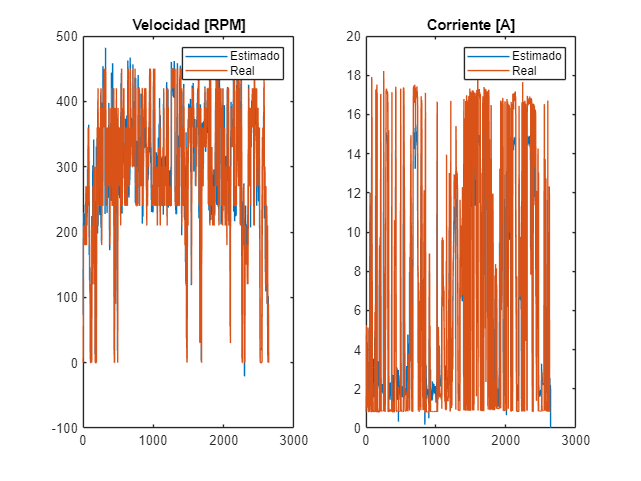

figure;
subplot(1, 2, 1)
plot(tnew,YnewEst(:,1), tnew, Yeval(:,1))
legend('Estimado', 'Real')
title('Velocidad [RPM]')
subplot(1, 2, 2)
plot(tnew, YnewEst(:,2), tnew, Yeval(:,2))
legend('Estimado', 'Real')
title('Corriente [A]')